# POST-PROCESSING OF IMAGES FROM PLANAR KIRIGAMI EXPERIMENTS

"Continuum Field Theory for the Deformations of Planar Kirigami" Yue Zheng, Imtiar Niloy, Paolo Celli, Ian Tobasco, and Paul Plucinsky Phys. Rev. Lett. 128, 208003 ? Published 20 May 2022

% Code created on July 2021

close all;
clear all;
clc;

## INPUT NEEDED -- CHOICE OF SPECIMEN/EXPERIMENTAL RESULT TO ANALYZE

filename='061521_AnIsoLRSidesCenterPull_v2_7cm'; para = [3 100]; % for Hyperbolic Pulling

%filename='060821_IsoLRSidesCenterPull_6cm'; para = [0 42]; % for Elliptic Pulling

% filename = '070121_ForcedIntoAnnulus_Hyperbolic'; para = [0 42]; % for Hyperbolic Annulus

% filename = '070121_ForcedIntoAnnulus_Elliptic'; para = [0 42]; % for Elliptic Annulus

%filename = '063021_Mixed_LRSidesCenterPull_6'; para = [0 100]; %Test for mixed

## IMAGE READ

I = imread([filename,'.tif']);

BW = imbinarize(I);
BW = logical(1 - BW);

stats = regionprops('table',BW,'Centroid','Area','MajorAxisLength','MinorAxisLength','Orientation');
Cent = stats.Centroid;
Area = stats.Area;
Maax = stats.MajorAxisLength;
Miax = stats.MinorAxisLength;
Orit = stats.Orientation;
Orit = -Orit/180*pi;

hinge = para(1);
Maax = Maax + hinge;
Maax(Maax>para(2))=para(2);

Angle=atan(Miax./Maax);
%xi_in = 0.32 %0.219; %For mixed kirigami
xi_in = 0.06; %0.06; %For hyperbolic kirigami
%xi_in = 0.09; %0.09; %For auxetic kirigami
Angle = Angle-xi_in;

## INPUT NEEDED -- CHOOSE SLIT THRESHOLDS

Slit=(Area>20 & Area<1000); % for Hyperbolic Pulling

%Slit=(Area>20 & Area<2300); % for Elliptic Pulling

% Slit=(Area>20 & Area<1000); % for Hyperbolic Annulus

% Slit=(Area>20 & Area<2000); % for Elliptic Annulus

%Slit=(Area>200 & Area<1700) & Maax < 60;% for Mixed Pulling

## PLOTS

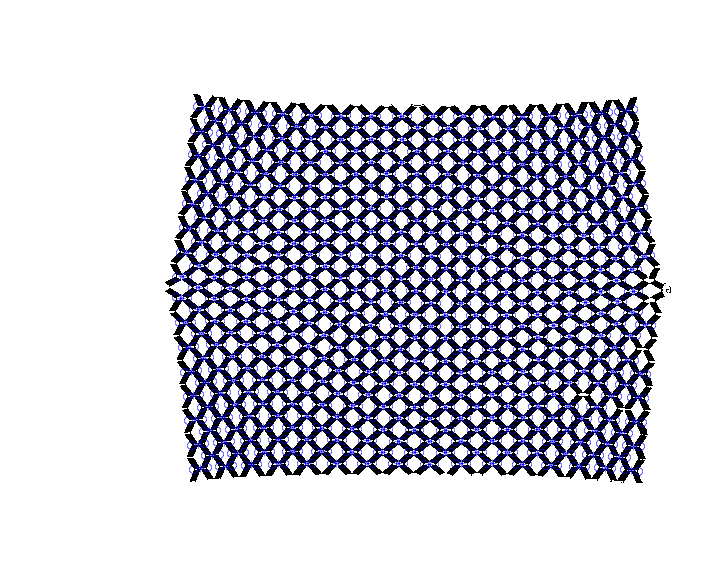

%disp(Cent(Slit,1))
%disp(Cent(Slit,2))
%disp(Angle(Slit))
%disp(Cent(Slit,1))

figure;
imshow(BW);
hold on;
plot(Cent(Slit,1),Cent(Slit,2),'b*')

plot([Cent(Slit,1)+Maax(Slit)/2.*cos(Orit(Slit)) Cent(Slit,1)-Maax(Slit)/2.*cos(Orit(Slit))]...
    ,[Cent(Slit,2)+Maax(Slit)/2.*sin(Orit(Slit)) Cent(Slit,2)-Maax(Slit)/2.*sin(Orit(Slit))],'bo')



figure;
subimage(BW);
hold on;
scatter2 = scatter(Cent(Slit,1),Cent(Slit,2),100,Angle(Slit),'filled')

scatter2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [541.7466 542.5317 556.5380 559.7051 567.7121 572 578.1343 584.5714 587.7143 595.5614 596.4158 605.5079 607.3750 604.8464 607.7864 609.6879 613.7016 618.6375 617.5866 619.7286 625.9738 627.9940 631.3542 635.1560 642.8889 643.7326 … ]
              YData: [1.1108e+03 1.0280e+03 1.2063e+03 933.8305 1.3025e+03 839.0397 1.3965e+03 744.3202 1.4903e+03 1.5858e+03 650.3663 1.6807e+03 555.8684 1.0695e+03 1.1561e+03 984.9408 1.7757e+03 461.7312 1.2489e+03 892.2596 1.3448e+03 365.7262 … ]
           SizeData: 100
              CData: [476×1 double]

  Show 

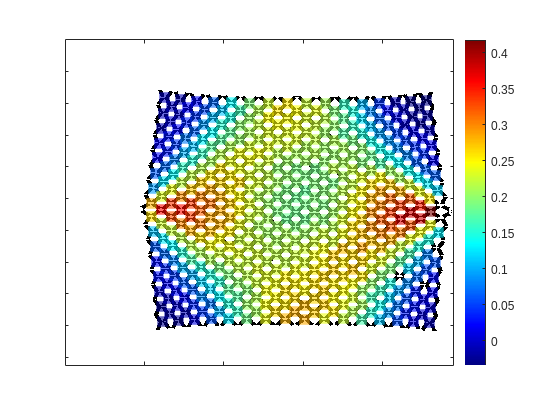

colormap jet;
scatter2.MarkerFaceAlpha = .6;
scatter2.Marker = 's';
set(gca,'XtickLabel',[],'YtickLabel',[])
colorbar